# Лабораторна робота №4

Яковець А., варіант 15

**1. За допомогою мікрофону ввести у комп'ютер аудіосигнал (назвіть свої  прізвище, ім’я та групу). Відтворити (прослухати) введену інформацію.**

clear
clearvars
clc
close all

t = 5;   % час запису в секундах
y = audiorecorder;  

disp('Почати запис')

Почати запис


recordblocking(y, t);
disp('Припинити запис')

Припинити запис



% зберігання даних у масиві
myRecording = getaudiodata(y);

% відтворення запису
play(y);
pause(5);

% другий спосіб відтворення
soundsc(myRecording);
pause(5);

**2. Змінити частоту дискретизації fs для пришвидшення та уповільнення  відтворення запису та відтворити отримані сигнали.**

% звичайна частота дискретизації 8192 Гц
% soundsc(myRecording, 8192, 16);
% pause(5);

% зменш вдвічі
soundsc(myRecording, 4096, 16);
pause(10);

% збільш вдвічі
soundsc(myRecording, 16384, 16);
pause(5);

**3. Записати введене аудіо у вигляді wav-файлу та mat-файлу. Вивести  інформацію про отриманий wav-файл.**

% запис аудіо у файли
filename = 'a.wav';
save('a.mat');
audiowrite(filename, myRecording, 8192);

% зчитування записаного файлу
[yy, fs] = audioread(filename);

% програвання зчитаного аудіо
sound(yy, fs);
pause(5);

% інф про wav файл
inf = audioinfo(filename)

inf = struct with fields:
             Filename: 'C:\Users\User\Documents\a.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8192
         TotalSamples: 40000
             Duration: 4.8828
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


**4.   Побудувати графік сигналу та його спектрограму, а також  амплітудний та фазовий спектри.**

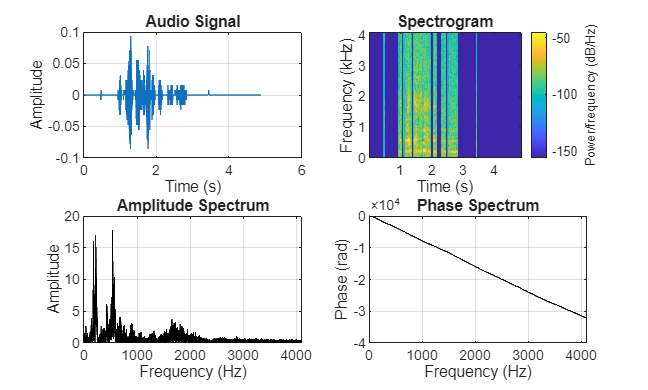

figure

% вісь часу
time = (0:length(yy)-1) / fs;

% Графік сигналу
subplot(2,2,1)
plot(time, yy)
grid
title('Audio Signal')
xlabel('Time (s)')
ylabel('Amplitude')

% Спектрограма сигналу
subplot(2,2,2)
spectrogram(yy, 256, 128, [], fs, 'yaxis')
title('Spectrogram')
xlabel('Time (s)')
ylabel('Frequency (kHz)')

% Амплітудний спектр
aspec = abs(fft(yy));
aspec = aspec(1:end/2);
afreq = (fs/2) * (1:length(aspec)) / length(aspec);

subplot(2,2,3)
plot(afreq, aspec, 'k')
grid
title('Amplitude Spectrum')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

% Фазовий спектр
fspec = phase(fft(yy));
fspec = fspec(1:end/2);
ffreq = (fs/2) * (1:length(fspec)) / length(fspec);

subplot(2,2,4)
plot(ffreq, fspec, 'k')
grid
title('Phase Spectrum')
xlabel('Frequency (Hz)')
ylabel('Phase (rad)')

**5. Завантажити файл сигналу у Signal Analyzer Toolbox та на його прикладі  дослідити можливості даного Toolbox, зокрема, отримати відповідні графіки,  спектрограми тощо. **

signalAnalyzer

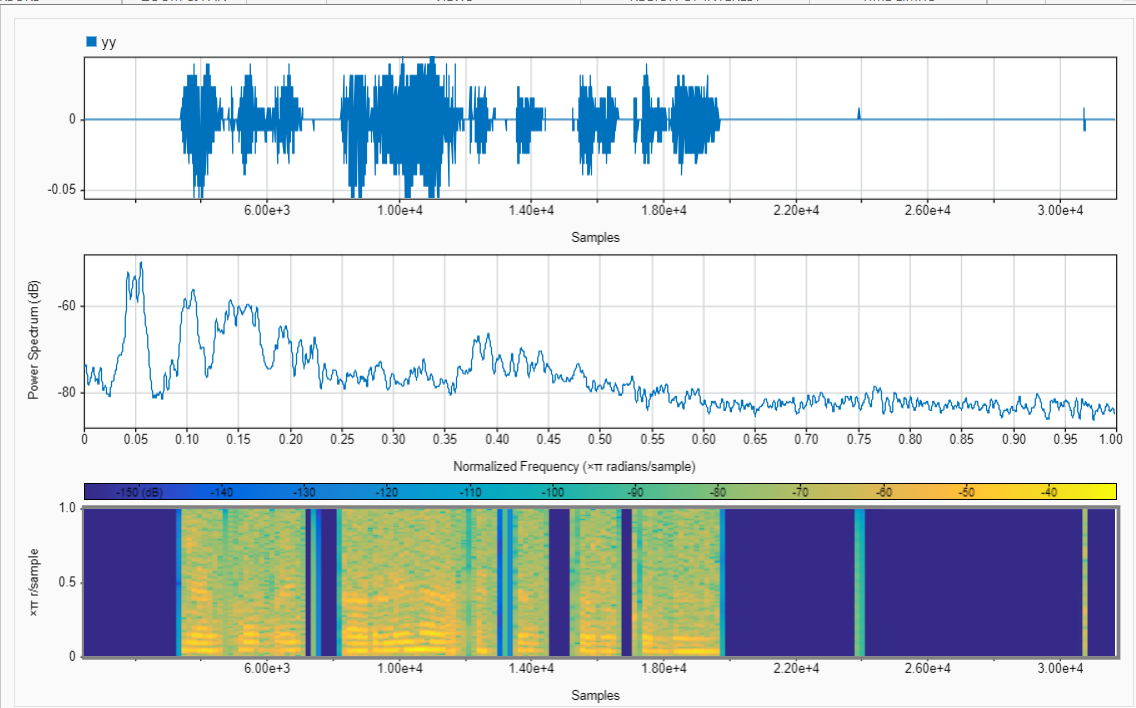

**6*. До аудіосигналу з п.1 додати шум (будь-якою функцією),  відфільтрувати зашумлений звуковий сигнал та порівняти отриманий сигнал з  початковим (шляхом порівняння відповідних графіків). **

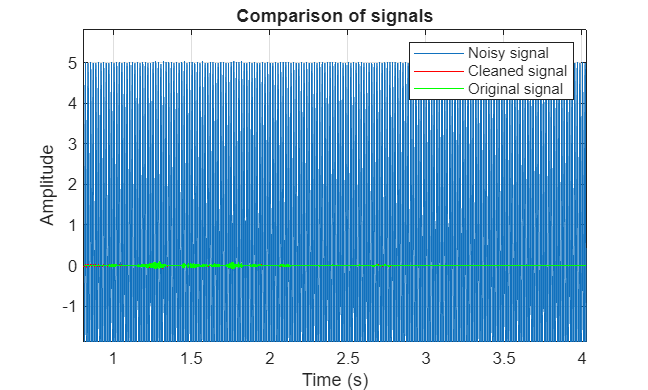

fs = 8192;

% вісь часу
time = (0:length(myRecording)-1) / fs;

% шум 60 Гц
noise = 5 * sin(2*pi*60*time)';   % стовпчик шуму
noisy_signal = myRecording + noise;

% зашумлений сигнал
sound(noisy_signal, fs);
pause(5);

% фільтрація
wo = 60/(fs/2);      % нормована частота
bw = wo/35;          % ширина смуги
[b, a] = iirnotch(wo, bw);

cleaned_signal = filtfilt(b, a, noisy_signal);

% очищений сигнал
sound(cleaned_signal, fs);
pause(5);

% графіки
figure
plot(time, noisy_signal)
hold on
plot(time, cleaned_signal, 'r')
plot(time, myRecording, 'g')
legend('Noisy signal', 'Cleaned signal', 'Original signal')
xlabel('Time (s)')
ylabel('Amplitude')
title('Comparison of signals')
grid